# BEV System Model - Simulation Case

modelName = "BEV_system_model";
load_system(modelName)
BEV_useComponents_Basic

Use Basic models for all components.


VehSpdRef_loadSimulationCase_SimpleDrivePattern( ...
  ModelName = modelName, ...
  TargetSubsystemPath = ...
    "/Controller & Environment" + ...
    "/Vehicle speed reference" )

Setting up simulation...
Simulation case: Simple drive pattern
Setting simulation stop time to 100 sec.
Selecting simulation case 1.


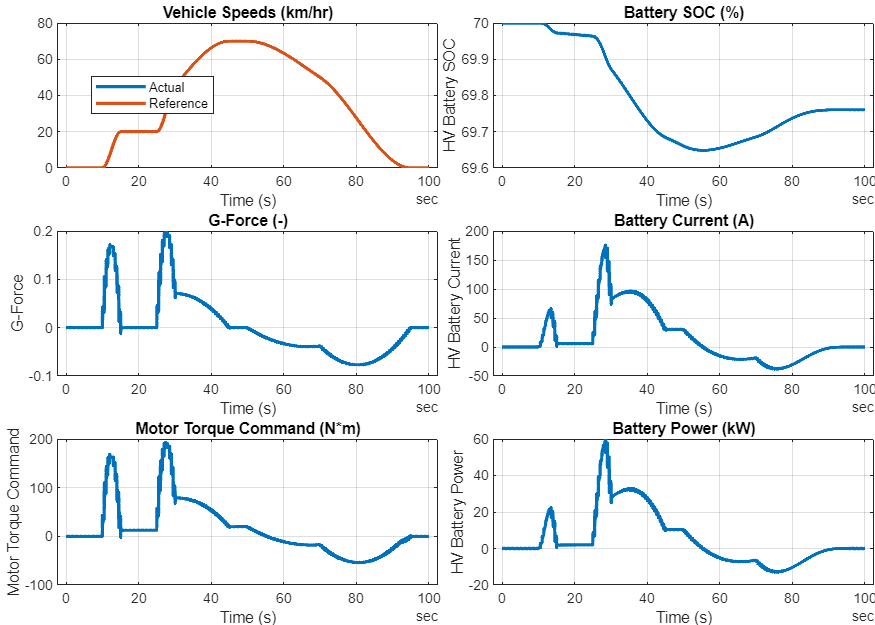

simOut = sim(modelName);
simData = extractTimetable(simOut.logsout);
fig = BEV_plotResultsCompact( SimData = simData, PlotTemperature = false );

*Copyright 2023 The MathWorks, Inc.*